## PART 2: Trajectory Planning 

In this part, the goal is to plan a trajectory which approximates the circular path from Problem 3 by means of 5 knot-points at *ϕ*0, *ϕ*9, *ϕ*18, *ϕ*27, *ϕ*36. 

### Problem 6:

Use the inverse computed joint confifigurations *q *(0) , *q *(9) , *q *(18) , *q *(27) , *q *(36) from Problem 3, to fifind suitable interpolation polynomials for the following segments: 

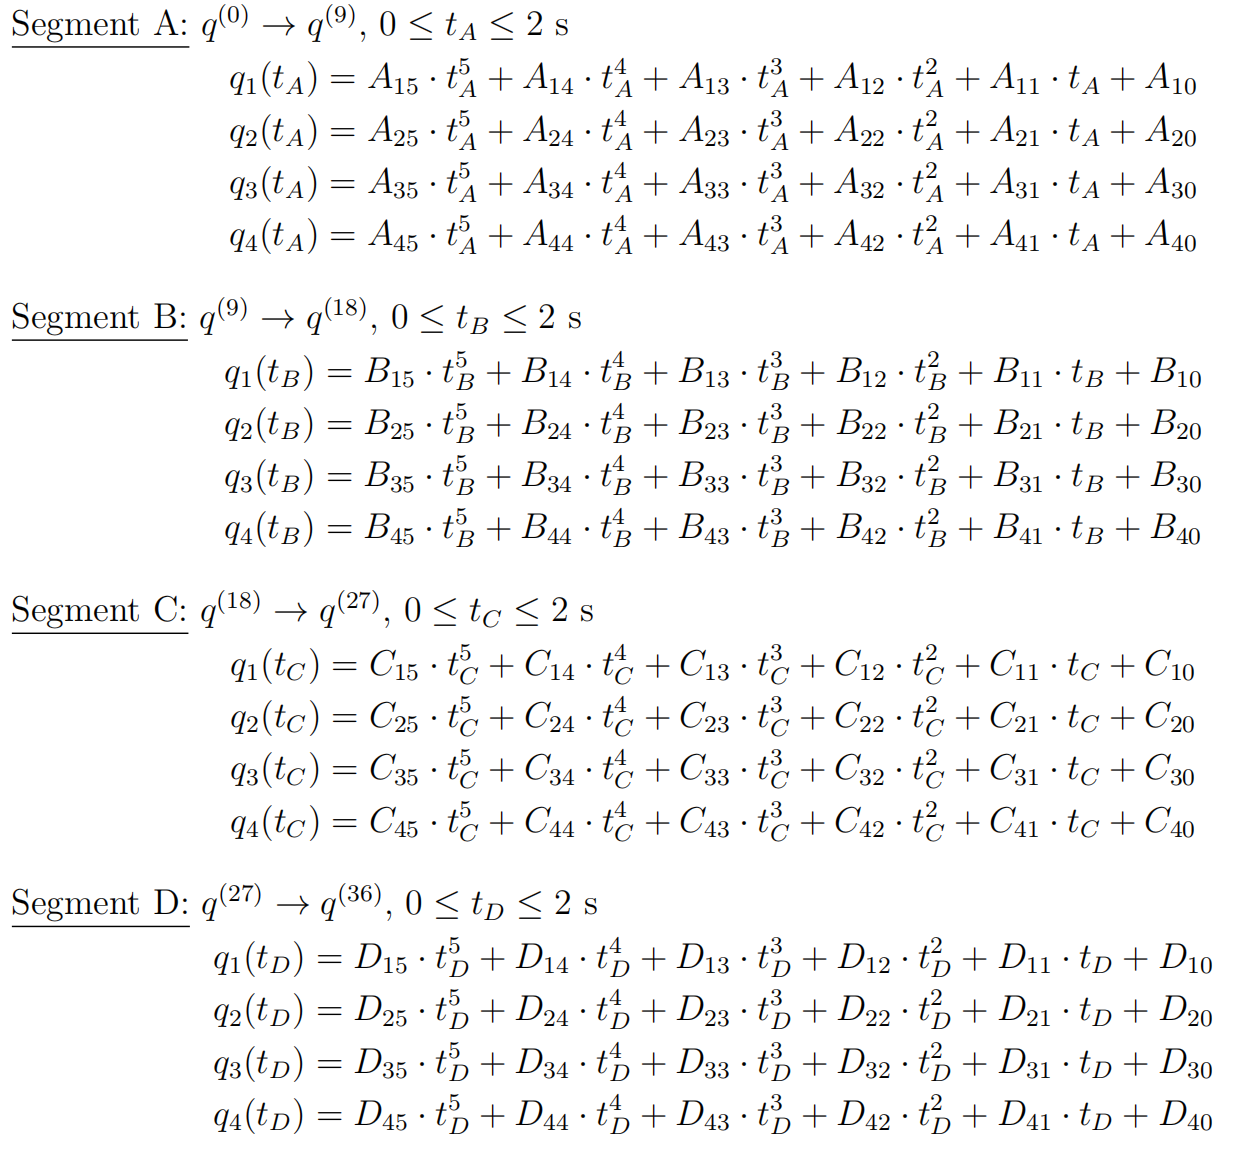

Determine the coeffiffifficients *A**ij *, *B**ij *, *C**ij *, *D**ij *so that 

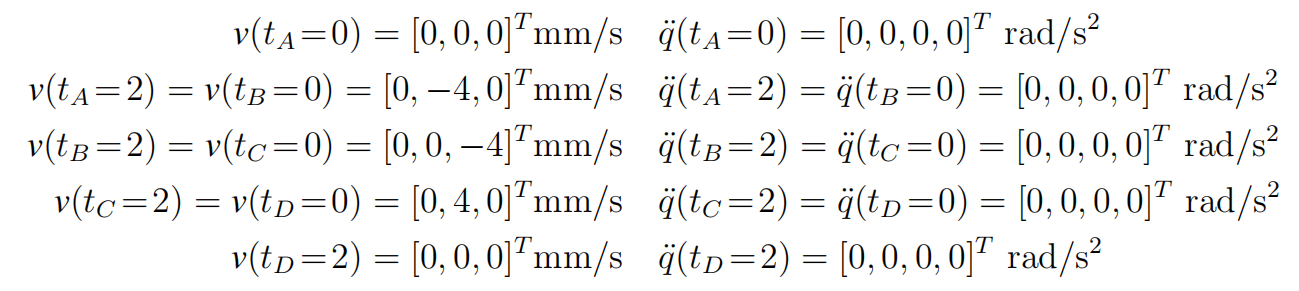

Hint: Note that end-effffector velocities *v *need to be converted to joint velocities ˙*q *and that requiring zero joint acceleration at knot points is maybe not the best but the simplest option. 

load("t1.mat");
load("t2.mat");
load("t3.mat");
load("t4.mat");

tIN = 0;%start point of each time interval
tOUT = 2;%end point of each time interval
MatrixofQ = [t1(1) t1(10) t1(19) t1(28) t1(37);
             t2(1) t2(10) t2(19) t2(28) t2(37);
             t3(1) t3(10) t3(19) t3(28) t3(37);
             t4(1) t4(10) t4(19) t4(28) t4(37)];%t(1), t(10), t(19), t(28), t(37) is
                                                %relative to q(0), q(9), q(18), q(27), q(36)
V0 = [0;0;0;0;0;0];
VA = [0;-4;0;0;0;0];
VB = [0;0;-4;0;0;0];
VC = [0;4;0;0;0;0];
VD = [0;0;0;0;0;0];
%vectors of end-effffector velocities v 
JA = getJacobian(10);

o04 =  -173.2162
         0
   48.2785


o14 =  -173.2162
         0
   48.2785


o24 =   -89.1045
  148.5503
         0


o34 =    92.3358
 -234.9552
         0


J =          0  -48.2785         0         0
 -173.2162         0         0         0
         0 -173.2162  -89.1045   92.3358
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


JB = getJacobian(19);

o04 =  -163.2115
         0
  -28.8473


o14 =  -163.2115
         0
  -28.8473


o24 =  -123.0441
  133.0979
         0


o34 =   123.1004
 -267.9202
         0


J =          0   28.8473         0         0
 -163.2115         0         0         0
         0 -163.2115 -123.0441  123.1004
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


JC = getJacobian(28);

o04 =  -167.1672
         0
   27.0025


o14 =  -167.1672
         0
   27.0025


o24 =  -111.6978
  126.4807
         0


o34 =   106.1632
 -248.9397
         0


J =          0  -27.0025         0         0
 -167.1672         0         0         0
         0 -167.1672 -111.6978  106.1632
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


JD = getJacobian(37);

o04 =  -156.6301
         0
   91.1506


o14 =  -156.6301
         0
   91.1506


o24 =   -77.2531
  142.3317
         0


o34 =    78.2293
 -220.6250
         0


J =          0  -91.1506         0         0
 -156.6301         0         0         0
         0 -156.6301  -77.2531   78.2293
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


%jaconbian matrix for calculating joint velocities ˙q
v0=0;
I=eye(4);
b=[0; 0; 0; 0];
JAp=inv(JA'*JA)*JA';
JBp=inv(JB'*JB)*JB';
JCp=inv(JC'*JC)*JC';
JDp=inv(JD'*JD)*JD';
vA=JAp*VA+(I-JAp*JA)*b;
vB=JBp*VB+(I-JBp*JB)*b;
vC=JCp*VC+(I-JCp*JC)*b;
vD=JDp*VD+(I-JDp*JD)*b;
%Calculation of joint velocities ˙q
ain = 0;
aout = 0;
%acceleration is always 0

A1 = getConstant(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1),ain,aout);
A2 = getConstant(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1),ain,aout);
A3 = getConstant(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1),ain,aout);
A4 = getConstant(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1),ain,aout);
A = [A1;A2;A3;A4];

B1 = getConstant(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1),ain,aout);
B2 = getConstant(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1),ain,aout);
B3 = getConstant(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1),ain,aout);
B4 = getConstant(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1),ain,aout);
B = [B1;B2;B3;B4];

C1 = getConstant(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1),ain,aout);

C2 = getConstant(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1),ain,aout);
C3 = getConstant(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1),ain,aout);
C4 = getConstant(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1),ain,aout);
C = [C1;C2;C3;C4];

D1 = getConstant(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1),ain,aout);

D2 = getConstant(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1),ain,aout);
D3 = getConstant(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1),ain,aout);
D4 = getConstant(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1),ain,aout);
D = [D1;D2;D3;D4];
%Calculation of Coefficients in Interpolation Functions

### Problem 7:

Plot the actual path of the end-effector as a function of time for the interpolated trajectory from Problem 6 and its deviation from the desired circular path. Try to improve the approximation either by using more knot-points or by using different interpolation functions than those found in Problem 6.

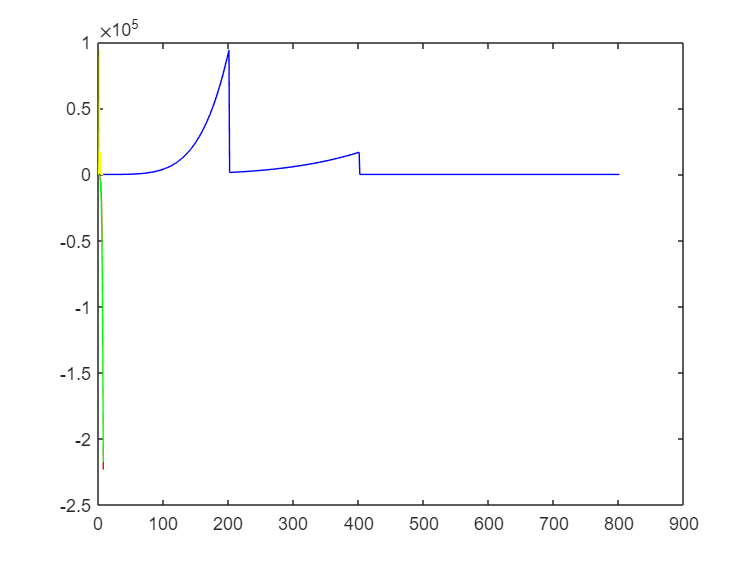

x = 0:0.01:8;
q1A = A1(6) * x.^5 + A1(5) * x.^4 + A1(4) * x.^3 + A1(3) * x.^2 + A1(2) * x + A1(1);
q2A = A2(6) * x.^5 + A2(5) * x.^4 + A2(4) * x.^3 + A2(3) * x.^2 + A2(2) * x + A2(1);
q3A = A3(6) * x.^5 + A3(5) * x.^4 + A3(4) * x.^3 + A3(3) * x.^2 + A3(2) * x + A3(1);
q4A = A4(6) * x.^5 + A4(5) * x.^4 + A4(4) * x.^3 + A4(3) * x.^2 + A4(2) * x + A4(1);

q1B = B1(6) * x.^5 + B1(5) * x.^4 + B1(4) * x.^3 + B1(3) * x.^2 + B1(2) * x + B1(1);
q2B = B2(6) * x.^5 + B2(5) * x.^4 + B2(4) * x.^3 + B2(3) * x.^2 + B2(2) * x + B2(1);
q3B = B3(6) * x.^5 + B3(5) * x.^4 + B3(4) * x.^3 + B3(3) * x.^2 + B3(2) * x + B3(1);
q4B = B4(6) * x.^5 + B4(5) * x.^4 + B4(4) * x.^3 + B4(3) * x.^2 + B4(2) * x + B4(1);

q1C = C1(6) * x.^5 + C1(5) * x.^4 + C1(4) * x.^3 + C1(3) * x.^2 + C1(2) * x + C1(1);
q2C = C2(6) * x.^5 + C2(5) * x.^4 + C2(4) * x.^3 + C2(3) * x.^2 + C2(2) * x + C2(1);
q3C = C3(6) * x.^5 + C3(5) * x.^4 + C3(4) * x.^3 + C3(3) * x.^2 + C3(2) * x + C3(1);
q4C = C4(6) * x.^5 + C4(5) * x.^4 + C4(4) * x.^3 + C4(3) * x.^2 + C4(2) * x + C4(1);

q1D = D1(6) * x.^5 + D1(5) * x.^4 + D1(4) * x.^3 + D1(3) * x.^2 + D1(2) * x + D1(1);
q2D = D2(6) * x.^5 + D2(5) * x.^4 + D2(4) * x.^3 + D2(3) * x.^2 + D2(2) * x + D2(1);
q3D = D3(6) * x.^5 + D3(5) * x.^4 + D3(4) * x.^3 + D3(3) * x.^2 + D3(2) * x + D3(1);
q4D = D4(6) * x.^5 + D4(5) * x.^4 + D4(4) * x.^3 + D4(3) * x.^2 + D4(2) * x + D4(1);
figure; % Create a new figure window
y1 = q1A.*(x>=0&x<=2) + q1B.*(x>2&x<=4) + q1C.*(x>4&x<=6) + q1D.*(x>6&x<=8);
plot(y1, 'b');
hold on
y2 = q2A.*(x>=0&x<=2) + q2B.*(x>2&x<=4) + q2C.*(x>4&x<=6) + q2D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q3A.*(x>=0&x<=2) + q3B.*(x>2&x<=4) + q3C.*(x>4&x<=6) + q3D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q4A.*(x>=0&x<=2) + q4B.*(x>2&x<=4) + q4C.*(x>4&x<=6) + q4D.*(x>6&x<=8);
plot(x, y1, 'y'); 

 
A71 = getConstant7(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1),ain,aout);
A72 = getConstant7(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1),ain,aout);
A73 = getConstant7(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1),ain,aout);
A74 = getConstant7(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1),ain,aout);
A7 = [A71 A72 A73 A74];
 
B71 = getConstant7(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1),ain,aout);
B72 = getConstant7(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1),ain,aout);
B73 = getConstant7(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1),ain,aout);
B74 = getConstant7(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1),ain,aout);
B7 = [B71 B72 B73 B74];

C71 = getConstant7(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1),ain,aout);

C72 = getConstant7(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1),ain,aout);
C73 = getConstant7(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1),ain,aout);
C74 = getConstant7(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1),ain,aout);
C7 = [C71 C72 C73 C74];

D71 = getConstant7(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1),ain,aout);

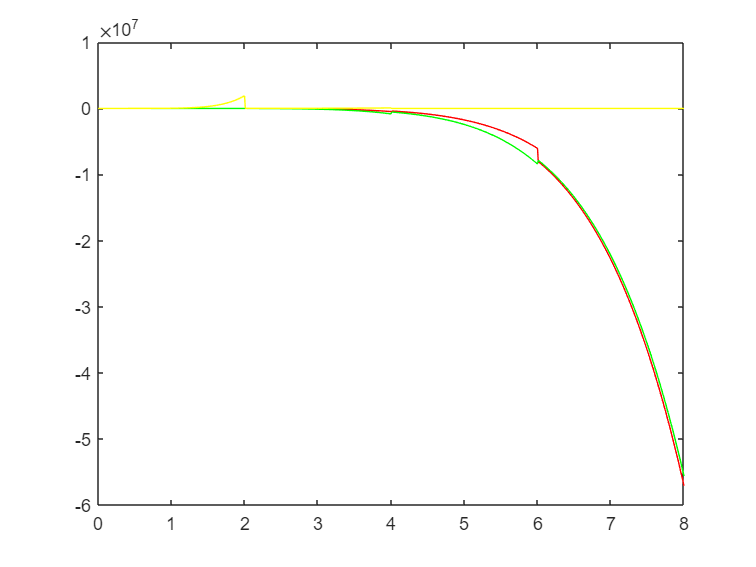

D72 = getConstant7(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1),ain,aout);
D73 = getConstant7(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1),ain,aout);
D74 = getConstant7(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1),ain,aout);
D7 = [D71 D72 D73 D74];

x = 0:0.01:8;
q71A = A71(8) * x.^7 + A71(7) * x.^6 + A71(6) * x.^5 + A71(5) * x.^4 + A71(4) * x.^3 + A71(3) * x.^2 + A71(2) * x + A71(1);
q72A = A72(8) * x.^7 + A72(7) * x.^6 + A72(6) * x.^5 + A72(5) * x.^4 + A72(4) * x.^3 + A72(3) * x.^2 + A72(2) * x + A72(1);
q73A = A73(8) * x.^7 + A73(7) * x.^6 + A73(6) * x.^5 + A73(5) * x.^4 + A73(4) * x.^3 + A73(3) * x.^2 + A73(2) * x + A73(1);
q74A = A74(8) * x.^7 + A74(7) * x.^6 + A74(6) * x.^5 + A74(5) * x.^4 + A74(4) * x.^3 + A74(3) * x.^2 + A74(2) * x + A74(1);

q71B = B71(8) * x.^7 + B71(7) * x.^6 + B71(6) * x.^5 + B71(5) * x.^4 + B71(4) * x.^3 + B71(3) * x.^2 + B71(2) * x + B71(1);
q72B = B72(8) * x.^7 + B72(7) * x.^6 + B72(6) * x.^5 + B72(5) * x.^4 + B72(4) * x.^3 + B72(3) * x.^2 + B72(2) * x + B72(1);
q73B = B73(8) * x.^7 + B73(7) * x.^6 + B73(6) * x.^5 + B73(5) * x.^4 + B73(4) * x.^3 + B73(3) * x.^2 + B73(2) * x + B73(1);
q74B = B74(8) * x.^7 + B74(7) * x.^6 + B74(6) * x.^5 + B74(5) * x.^4 + B74(4) * x.^3 + B74(3) * x.^2 + B74(2) * x + B74(1);

q71C = C71(8) * x.^7 + C71(7) * x.^6 + C71(6) * x.^5 + C71(5) * x.^4 + C71(4) * x.^3 + C71(3) * x.^2 + C71(2) * x + C71(1);
q72C = C72(8) * x.^7 + C72(7) * x.^6 + C72(6) * x.^5 + C72(5) * x.^4 + C72(4) * x.^3 + C72(3) * x.^2 + C72(2) * x + C72(1);
q73C = C73(8) * x.^7 + C73(7) * x.^6 + C73(6) * x.^5 + C73(5) * x.^4 + C73(4) * x.^3 + C73(3) * x.^2 + C73(2) * x + C73(1);
q74C = C74(8) * x.^7 + C74(7) * x.^6 + C74(6) * x.^5 + C74(5) * x.^4 + C74(4) * x.^3 + C74(3) * x.^2 + C74(2) * x + C74(1);

q71D = D71(8) * x.^7 + D71(7) * x.^6 + D71(6) * x.^5 + D71(5) * x.^4 + D71(4) * x.^3 + D71(3) * x.^2 + D71(2) * x + D71(1);
q72D = D72(8) * x.^7 + D72(7) * x.^6 + D72(6) * x.^5 + D72(5) * x.^4 + D72(4) * x.^3 + D72(3) * x.^2 + D72(2) * x + D72(1);
q73D = D73(8) * x.^7 + D73(7) * x.^6 + D73(6) * x.^5 + D73(5) * x.^4 + D73(4) * x.^3 + D73(3) * x.^2 + D73(2) * x + D73(1);
q74D = D74(8) * x.^7 + D74(7) * x.^6 + D74(6) * x.^5 + D74(5) * x.^4 + D74(4) * x.^3 + D74(3) * x.^2 + D74(2) * x + D74(1);
figure; % Create a new figure window
y1 = q71A.*(x>=0&x<=2) + q71B.*(x>2&x<=4) + q71C.*(x>4&x<=6) + q71D.*(x>6&x<=8);
plot(x, y1, 'b');
hold on
y2 = q72A.*(x>=0&x<=2) + q72B.*(x>2&x<=4) + q72C.*(x>4&x<=6) + q72D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q73A.*(x>=0&x<=2) + q73B.*(x>2&x<=4) + q73C.*(x>4&x<=6) + q73D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q74A.*(x>=0&x<=2) + q74B.*(x>2&x<=4) + q74C.*(x>4&x<=6) + q74D.*(x>6&x<=8);
plot(x, y1, 'y'); 

A31 = getConstant3(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1));
A32 = getConstant3(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1));
A33 = getConstant3(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1));
A34 = getConstant3(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1));
A3 = [A31 A32 A33 A34];
 
B31 = getConstant3(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1));
B32 = getConstant3(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1));
B33 = getConstant3(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1));
B34 = getConstant3(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1));
B3 = [B31 B32 B33 B34];

C31 = getConstant3(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1));

C32 = getConstant3(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1));
C33 = getConstant3(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1));
C34 = getConstant3(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1));
C3 = [C31 C32 C33 C34];

D31 = getConstant3(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1));

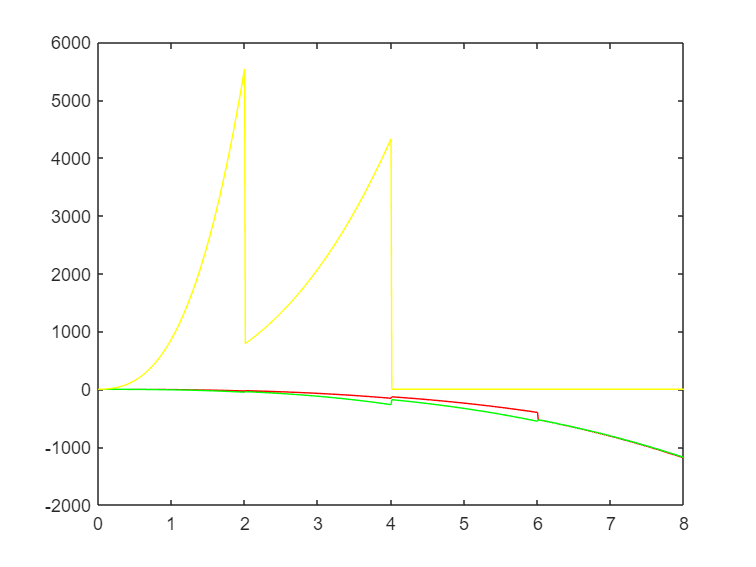

D32 = getConstant3(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1));
D33 = getConstant3(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1));
D34 = getConstant3(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1));
D3 = [D31 D32 D33 D34];

x = 0:0.01:8;
q31A = A31(4) * x.^3 + A31(3) * x.^2 + A31(2) * x + A31(1);
q32A = A32(4) * x.^3 + A32(3) * x.^2 + A32(2) * x + A32(1);
q33A = A33(4) * x.^3 + A33(3) * x.^2 + A33(2) * x + A33(1);
q34A = A34(4) * x.^3 + A34(3) * x.^2 + A34(2) * x + A34(1);

q31B = B31(4) * x.^3 + B31(3) * x.^2 + B31(2) * x + B31(1);
q32B = B32(4) * x.^3 + B32(3) * x.^2 + B32(2) * x + B32(1);
q33B = B33(4) * x.^3 + B33(3) * x.^2 + B33(2) * x + B33(1);
q34B = B34(4) * x.^3 + B34(3) * x.^2 + B34(2) * x + B34(1);

q31C = C31(4) * x.^3 + C31(3) * x.^2 + C31(2) * x + C31(1);
q32C = C32(4) * x.^3 + C32(3) * x.^2 + C32(2) * x + C32(1);
q33C = C33(4) * x.^3 + C33(3) * x.^2 + C33(2) * x + C33(1);
q34C = C34(4) * x.^3 + C34(3) * x.^2 + C34(2) * x + C34(1);

q31D = D31(4) * x.^3 + D31(3) * x.^2 + D31(2) * x + D31(1);
q32D = D32(4) * x.^3 + D32(3) * x.^2 + D32(2) * x + D32(1);
q33D = D33(4) * x.^3 + D33(3) * x.^2 + D33(2) * x + D33(1);
q34D = D34(4) * x.^3 + D34(3) * x.^2 + D34(2) * x + D34(1);
figure; % Create a new figure window
y1 = q31A.*(x>=0&x<=2) + q31B.*(x>2&x<=4) + q31C.*(x>4&x<=6) + q31D.*(x>6&x<=8);
plot(x, y1, 'b');
hold on
y2 = q32A.*(x>=0&x<=2) + q32B.*(x>2&x<=4) + q32C.*(x>4&x<=6) + q32D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q33A.*(x>=0&x<=2) + q33B.*(x>2&x<=4) + q33C.*(x>4&x<=6) + q33D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q34A.*(x>=0&x<=2) + q34B.*(x>2&x<=4) + q34C.*(x>4&x<=6) + q34D.*(x>6&x<=8);
plot(x, y1, 'y'); 